close("all"); clear; clc;

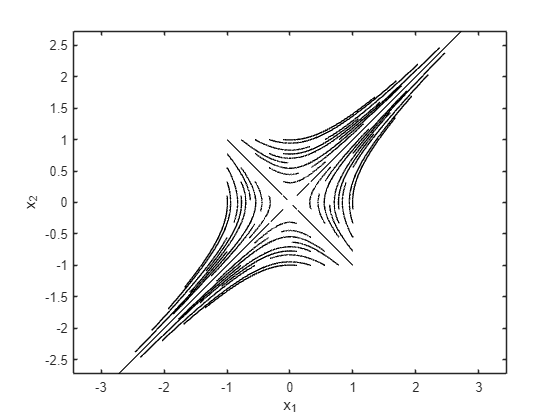

A = fliplr(eye(2));
sys = ss(A,zeros(2,1),eye(2),0);
figA = plotIntegralCurves(sys);

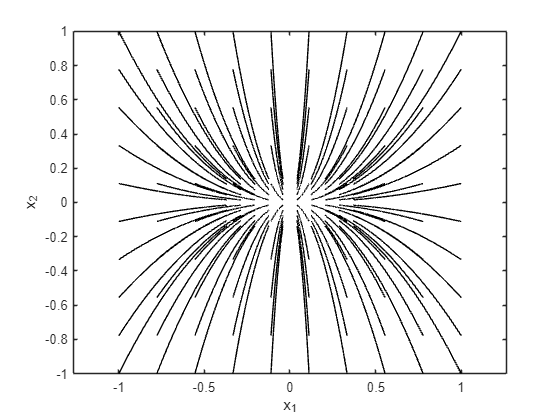

B = [
    -1,0;
    0,-2
    ];

sys = ss(B,zeros(2,1),eye(2),0);
figB = plotIntegralCurves(sys);

t = sym('t');
x = arrayfun(@(k)dsym("x_" + k),1:2).';

solA = symdsolve(diff(x,t) - A*x)

$$solA = \left[\begin{array}{c} C_{1}\,{\mathrm{e}}^{t}+C_{2}\,{\mathrm{e}}^{-t}\\ C_{1}\,{\mathrm{e}}^{t}-C_{2}\,{\mathrm{e}}^{-t} \end{array}\right]$$

solB = symdsolve(diff(x,t) - B*x)

$$solB = \left[\begin{array}{c} C_{2}\,{\mathrm{e}}^{-2\,t}\\ C_{1}\,{\mathrm{e}}^{-t} \end{array}\right]$$

function x = dsym(name)
    arguments
        name (1,1) string;
    end
    fx = symfun(name + "(t)",sym('t'));
    x = fx(sym('t'));
end

function sol = symdsolve(eqns,conds)
    arguments
        eqns (:,1) sym;
        conds (:,1) sym = sym.empty(0,1);
    end
    y = dsolve(eqns,conds);
    sol = cell2sym(struct2cell(y));
end

function fig = plotIntegralCurves(sys)
    t = linspace(0,1,1000);
    u = 0.*t;
    x0 = linspace(-1,1,10);
    [X1,X2] = meshgrid(x0,x0);
    X0 = [X1(:),X2(:)];

    fig = figure();
    axe = axes(fig);
    for k = 1:size(X0,1)
        y = lsim(sys,u,t,X0(k,:));
        hold(axe,"on");
        plot(axe,y(:,1),y(:,2),"Color",'k');
        hold(axe,"off");
    end
    axis(axe,"equal");
    box(axe,"on");
    xlabel("x_1");
    ylabel("x_2");
end